clearvars
clc

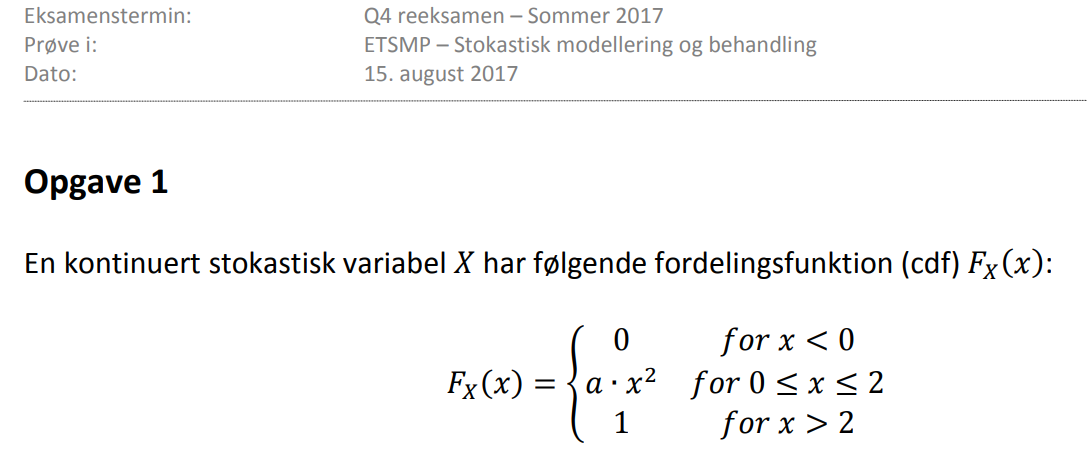

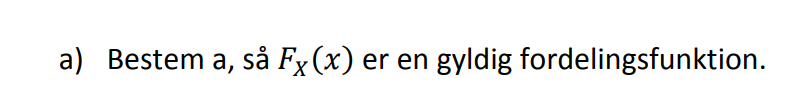

Vi ved at 

syms a x
Fx(x) = piecewise(0 > x, 0, 0 <= x <= 2, a * x^2,  x > 2, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ a\,x^{2} & \text{ if }x\in \left[0,2\right]\\ 1 & \text{ if }2<x \end{array}\right.$$

a = solve(Fx(2) == 1, a)

$$a = \frac{1}{4}$$

a = 1/4

a = 0.2500

Fx(x) = piecewise(0 > x, 0, 0 <= x <= 2, a * x^2,  x > 2, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{x^{2}}{4} & \text{ if }x\in \left[0,2\right]\\ 1 & \text{ if }2<x \end{array}\right.$$

fx(x) = diff(Fx(x))

$$fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{x}{2} & \text{ if }x\in \left(0,2\right)\\ 0 & \text{ if }2<x \end{array}\right.$$

fplot(fx(x), [-4, 4],'-r','LineWidth',2)

title('Tæthedsfunktion')
xlabel('x')
ylabel('y')

Pr = (1-Fx(1))-(1-Fx(2))

$$Pr = \frac{3}{4}$$

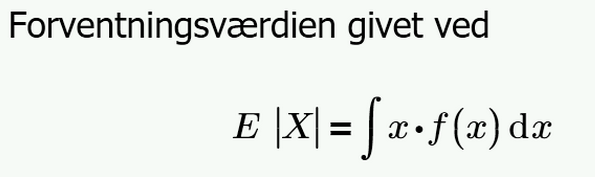

Ex=int(x*fx(x),'x',-Inf,Inf)

$$Ex = \frac{4}{3}$$

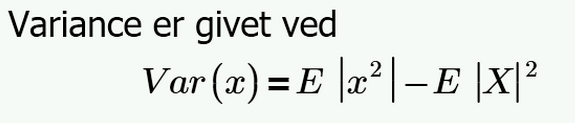

var = int(x^2*fx(x),'x',-Inf,Inf)-(Ex^2)

$$var = \frac{2}{9}$$

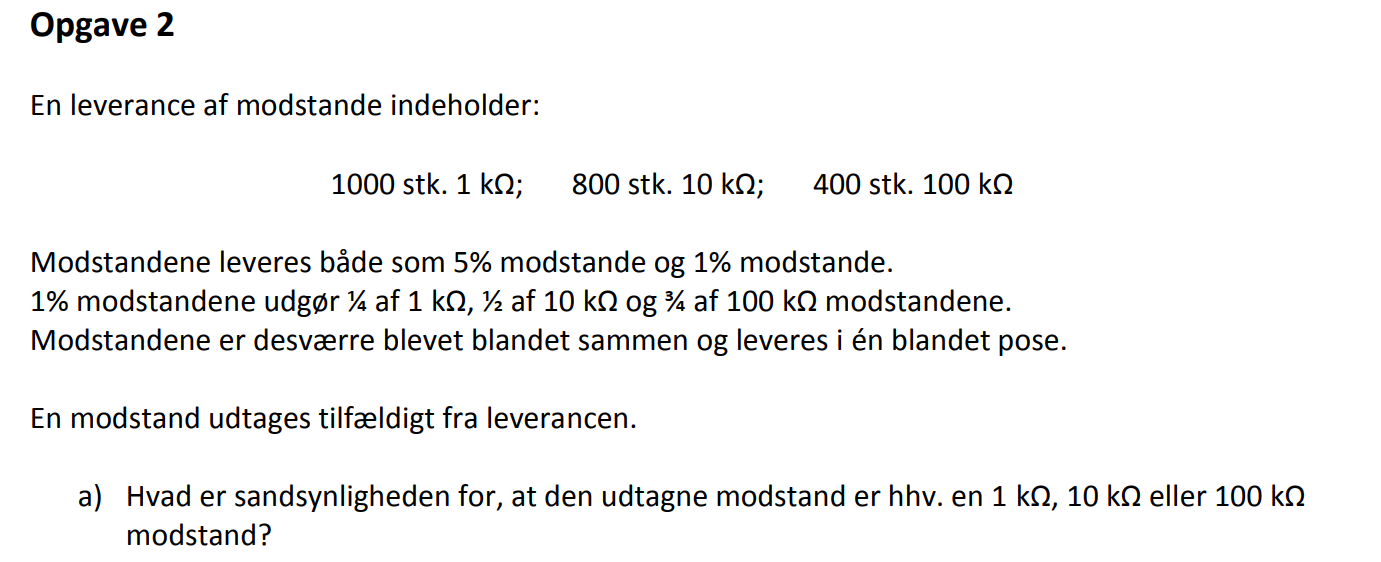

total = 1000+800+400;
Pr_1k = 1000/total

Pr_1k = 0.4545

Pr_10k = 800 / total

Pr_10k = 0.3636

Pr_100k = 400/total

Pr_100k = 0.1818

1/2 af 10k modstandene er 1 %

Pr_10k_1p = Pr_10k*1/2

Pr_10k_1p = 0.1818

1/4 af 1k er 1 % 

3/4 af 100k er 1 %

Summer sandsynlighederne sammen 

Pr_all_1p = Pr_10k_1p + (Pr_1k*1/4) + (Pr_100k*3/4)

Pr_all_1p = 0.4318

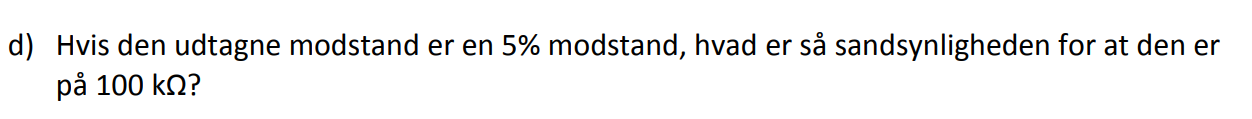

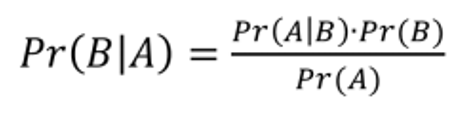

Pr_all_5p = 1 - Pr_all_1p;
Pr_100k_5p  = 1 - 3/4

Pr_100k_5p = 0.2500

(Pr_100k*Pr_100k_5p)/Pr_all_5p

ans = 0.0800

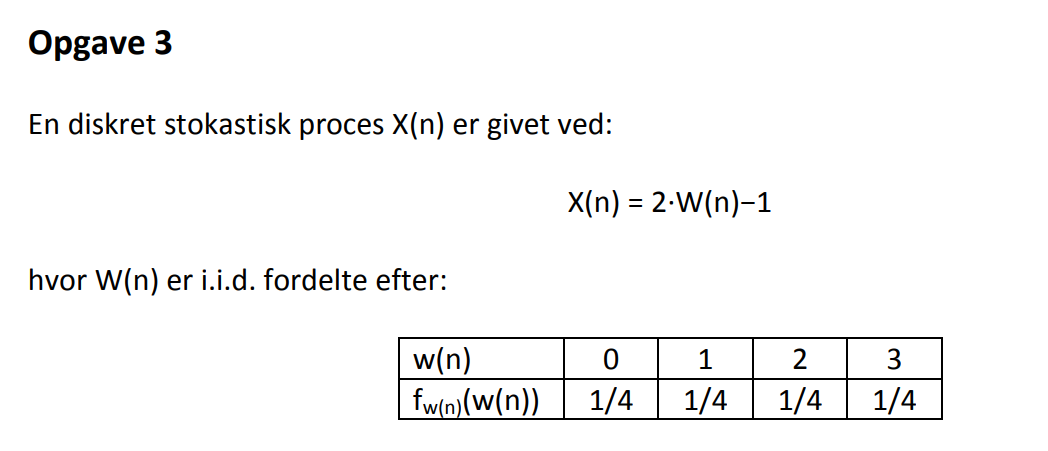

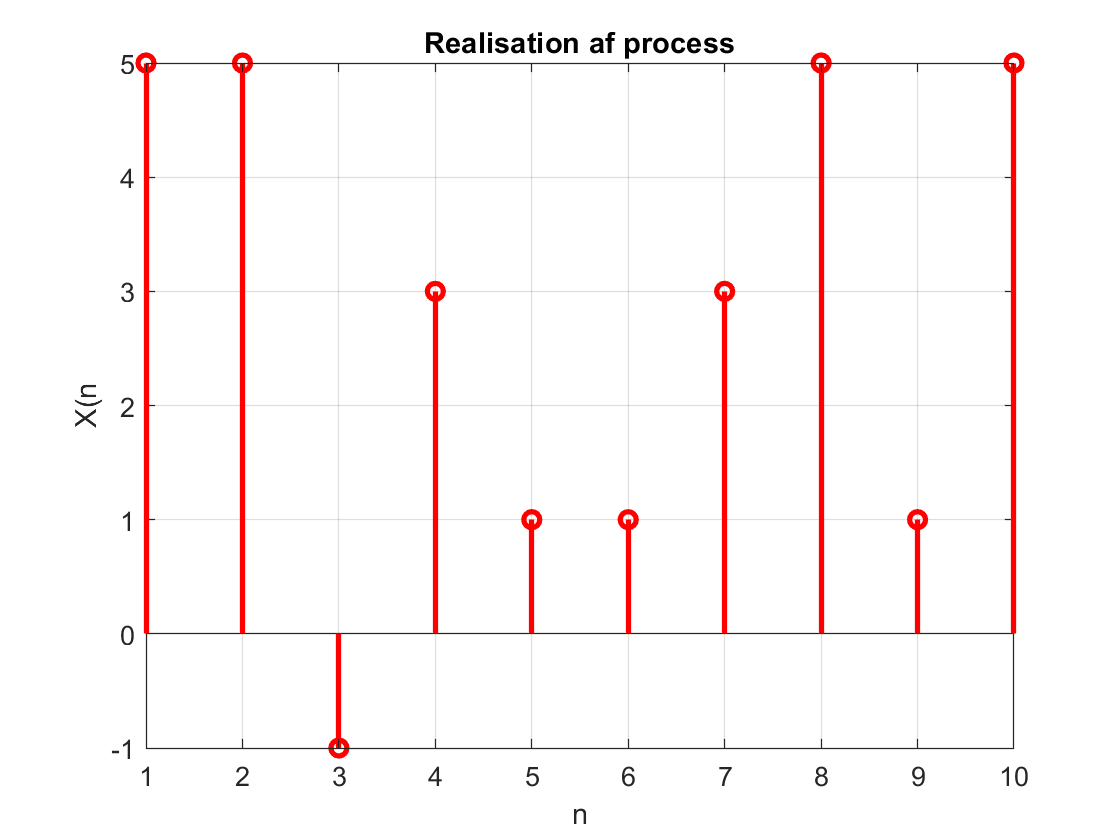

clear all
close all

% unidrnd returner et array med random værdier der er uniformt fordelt fra 
% {1, 2, ..., max}. For at få 0; 1; 2; 3; shiftes arrayet ved at trække 1 fra!
% Der skal generes 4 værdier hvilket giver max = 4.
N = 10; % Antal samples
max = 4;
w = unidrnd(max, 1, N) - 1;
Xn = 2*w-1;
x = [1:1:N];
figure()
stem(x,Xn,'-r','LineWidth',2)
grid on
xlabel("n"); ylabel("X(n"); title("Realisation af process");

middel = mean(2*w-1)

middel = 2.8000

varianse = var(Xn)

varianse = 4.8444

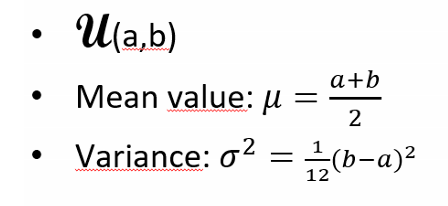

middel = 2*(0+3/2)-1

middel = 2

var = var(middel*2-1)

var = 0

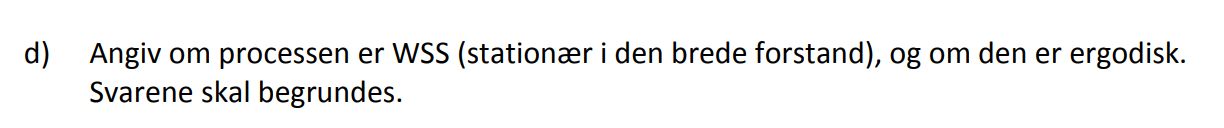

Da processen er uafhængig af tiden, og at middelværdien og variansen ikke ændrer sig over tid, så kan vi konstanter at processen er stationær.

Processen er egodisk da pmf kan bestemmes udfra en realisation

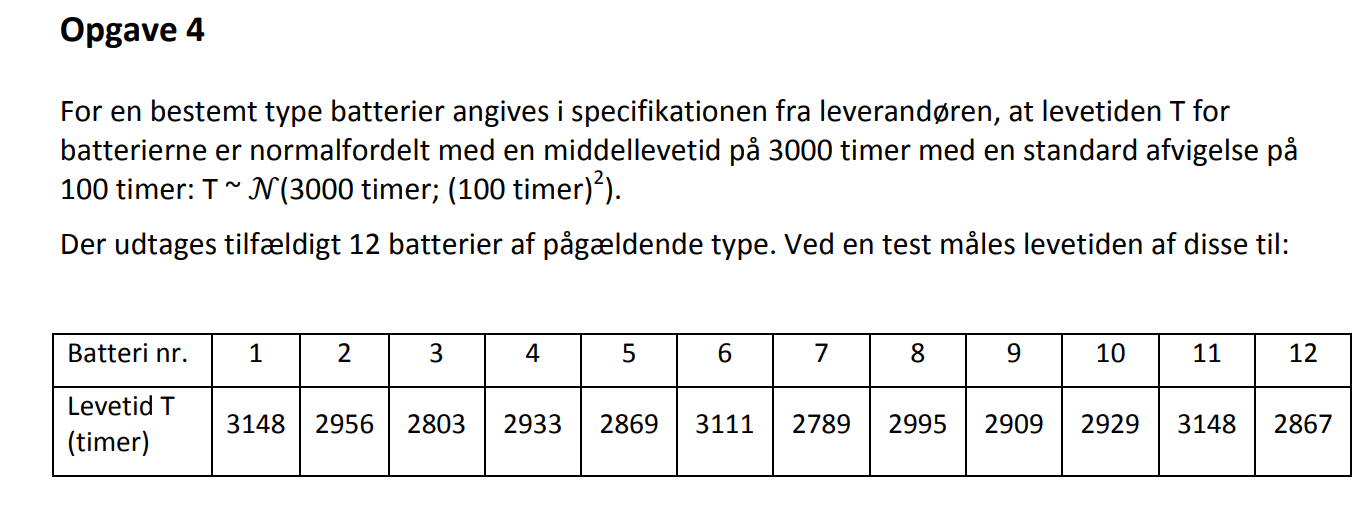

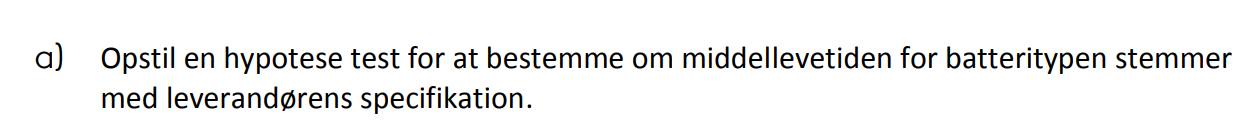

Null hypothesis. Brugt som testen af ingen forskel.


$$H_0 =\mu 1=\mu 2$$


Alternanive hypotese


$$H_1 =\mu 1\not= \mu 2$$


Batteri = 1:12;
T = [3148 2956 2803 2933 2869 3111 2789 2995 2909 2929 3148 2867];
middel = sum(T)/length(Batteri)

middel = 2.9548e+03

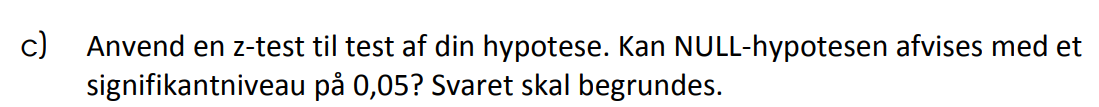

mu0 = 3000; % hypoteste
sigma = 100; %afvigelse
z = (middel-mu0)/(sigma/sqrt(length(Batteri))); % teststørrelse
pval = 2 * (1 - normcdf(abs(z)))

pval = 0.1170

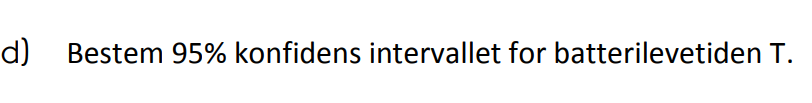

## 95% konfidens interval - Known variance

mu_lower = middel - 1.96 * (sigma/sqrt(length(Batteri)))

mu_lower = 2.8982e+03

mu_upper = middel + 1.96 * (sigma/sqrt(length(Batteri)))

mu_upper = 3.0113e+03